flights = importFlightsData("flightsJan.csv");
airports = readtable("airports.csv", "TextType", "string");
airports.AIRPORT = categorical(airports.AIRPORT);

### EXERCISE WEEK 2

airportCityNames = airports.DISPLAY_AIRPORT_CITY_NAME_FULL;
tmp = split(airportCityNames,','); cities = tmp(:,1); states = strtrim(tmp(:,2));
airports.STATE = states;
airportsSorted = sortrows(airports,{'STATE','AIRPORT'},'ascend')

airportsSorted = 322×6 table
    AIRPORT          DISPLAY_AIRPORT_NAME           DISPLAY_AIRPORT_CITY_NAME_FULL    LATITUDE    LONGITUDE    STATE
    _______    _________________________________    ______________________________    ________    _________    _____

      ADK      "Adak NS"                                  "Adak Island, AK"            51.883      -176.64     "AK" 
      ADQ      "Kodiak Airport"                           "Kodiak, AK"                  57.75      -152.49     "AK" 
      AKN      "King Salmon Airport"                      "King Salmon, AK"            58.678      -156.65     "AK" 
      ANC      "Anchorage International"                  "Anchorage, AK"              61.169      -149.99     "AK" 
      BET      "Bethel Airport"                           "Bethe

% Join tables
flightsAndLocations = outerjoin(airports,flights,"LeftKeys","AIRPORT","RightKeys",...
    "ORIGIN","MergeKeys",true)

flightsAndLocations = 469978×25 table
    AIRPORT_ORIGIN        DISPLAY_AIRPORT_NAME          DISPLAY_AIRPORT_CITY_NAME_FULL     LATITUDE    LONGITUDE    STATE              AIRLINE              TAIL_NUMBER    FLIGHT_NUMBER    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    ______________    _________

flightCount = groupsummary(flightsAndLocations,"STATE");
flightCount = sortrows(flightCount,'GroupCount')

flightCount = 55×2 table
         STATE          GroupCount
    ________________    __________

    "American Samoa"         10   
    "DE"                     26   
    "Guam"                   31   
    "WV"                    176   
    "ME"                    227   
    "VT"                    241   
    "NH"                    469   
    "Virgin Islands"        567   
    "SD"                    880   
    "WY"                    884   
    "KS"                    929   
    "RI"                   1024   
    "MT"                   1057   
    "MS"                   1191   
    "ID"                   1409   
    "ND"                   1497   


flightCount = sortrows(flightCount,"GroupCount","ascend");

checkTZ = abs(flightsAndLocations.SCHEDULED_ELAPSED_TIME ...
    - 60*24*datenum(flightsAndLocations.ACTUAL_ARRIVAL_TIME-flightsAndLocations.ACTUAL_DEPARTURE_TIME));
% flight time only counts minutes, not second --> if checkTZ smaller than 1
% minute, convert all to 0 minute, meaning no time zone change
checkTZ(checkTZ<1) = 0;
changeTZ = length(checkTZ) - sum(checkTZ==0);
changeTZ/length(checkTZ)

ans = 0.9795

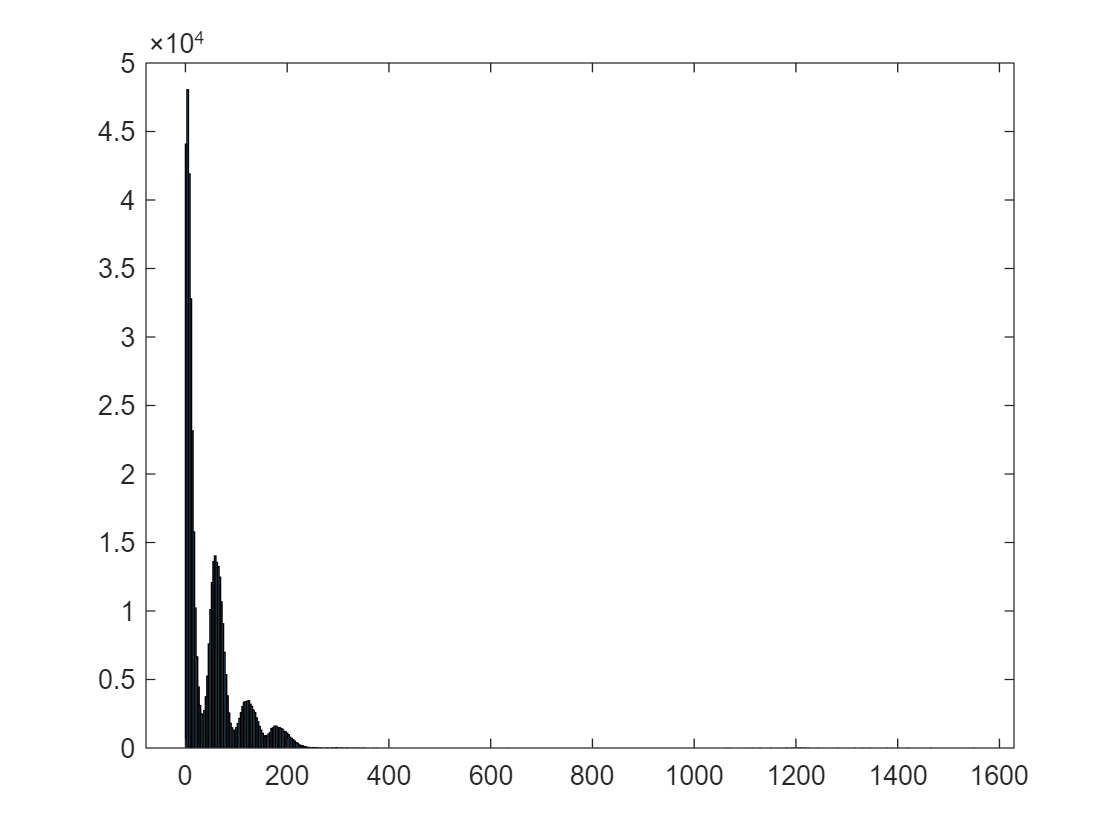

histogram(rmmissing(checkTZ))

### EXERCISE WEEK 3

hasMissing = nnz(sum(ismissing(flights),1))

hasMissing = 10

flights.SCHEDULED_DEPARTURE_HOUR = dateshift(flights.SCHEDULED_DEPARTURE_TIME,"start","hour");
flightsNotArriving = groupsummary(flights,"SCHEDULED_DEPARTURE_HOUR","sum",["DIVERTED" , "CANCELLED"]);
flightsNotArriving.Properties.VariableNames = [ "Scheduled_Departure_Hour" "Total_Flights" "Diverted_Flights" "Cancelled_Flights"];
Cancelled_Flights = rmoutliers(flightsNotArriving.Cancelled_Flights,'quartiles');
Diverted_Flights = rmoutliers(flightsNotArriving.Diverted_Flights,'quartiles');
% plot(flightsNotArriving.Scheduled_Departure_Hour,flightsNotArriving.Cancelled_Flights)

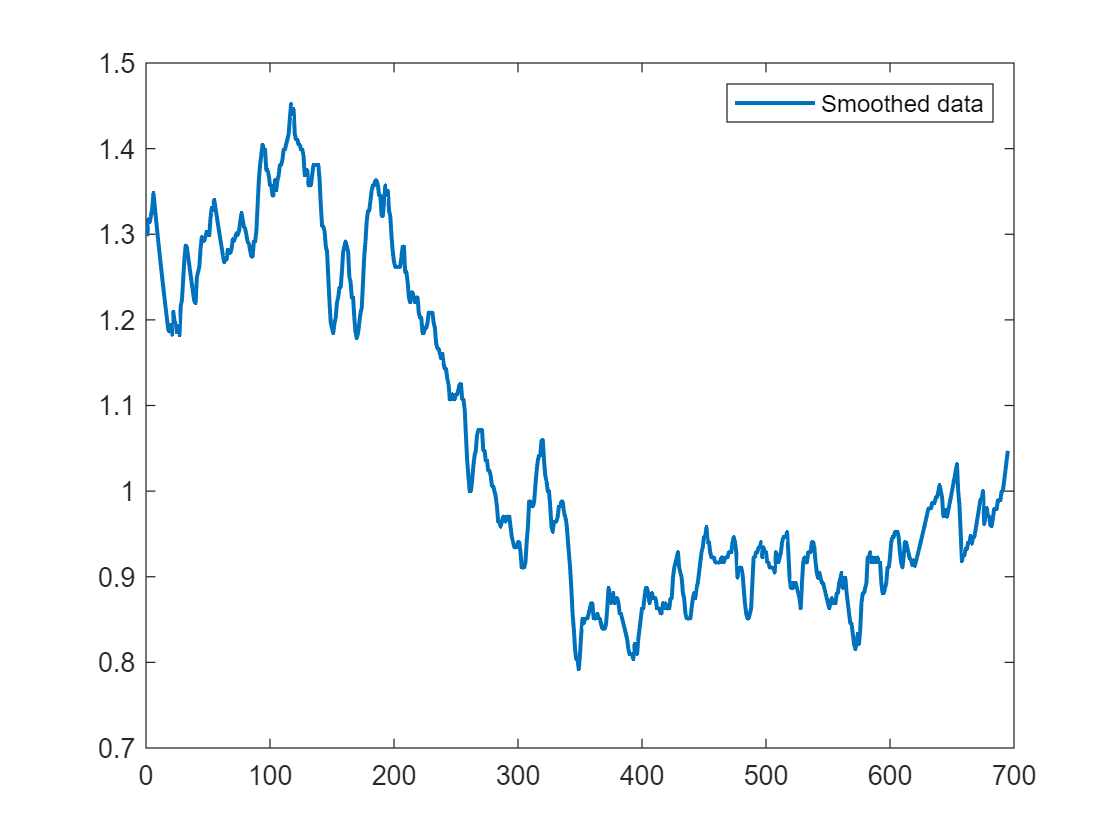

% Smooth input data
smoothedDivertedFlights = smoothdata(Diverted_Flights,"movmean",168);

% Display results
clf
plot(smoothedDivertedFlights,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
legend

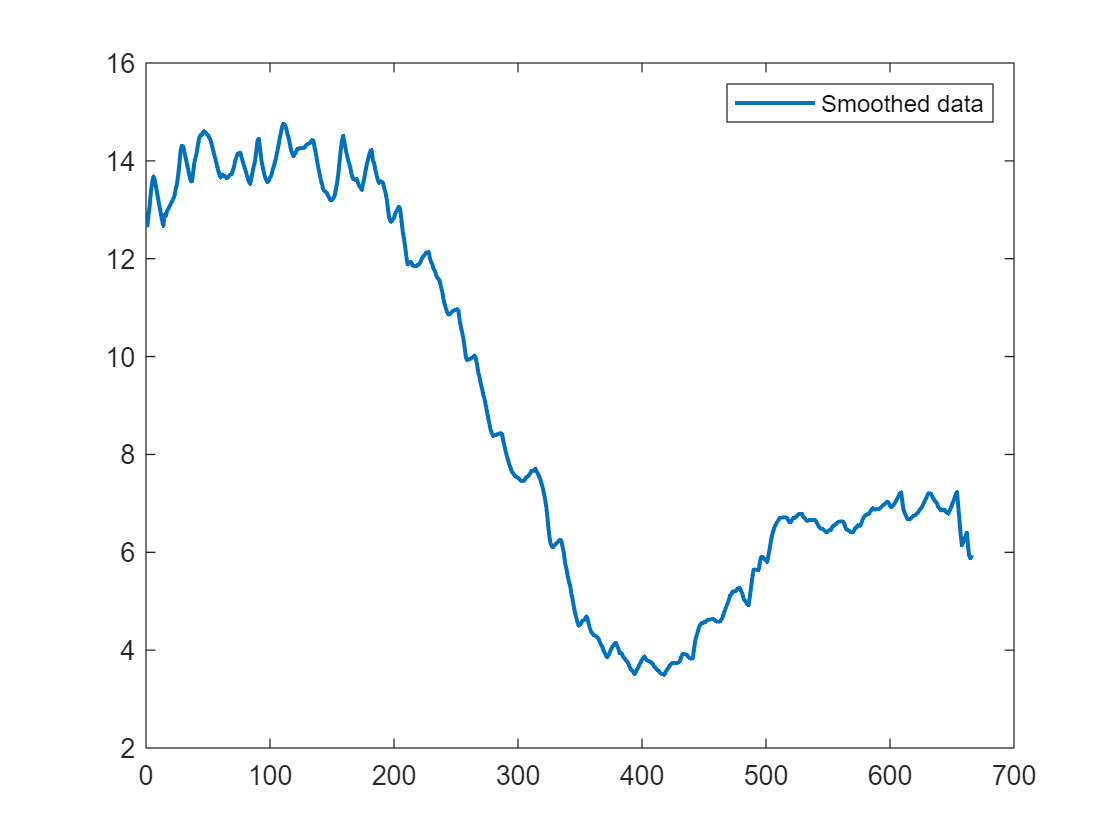

% Smooth input data
smoothedCancelledFlights = smoothdata(Cancelled_Flights,"movmean",168);

% Display results
clf
plot(smoothedCancelledFlights,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
legend

corrcoef(smoothedCancelledFlights,smoothedDivertedFlights(1:666))

ans =     1.0000    0.9604
    0.9604    1.0000
